**ECE537 Programming Assignment 5**

Yuan Sui

1a) Generate zero-mean unit variance gaussian iid Nn and AR filter Xn

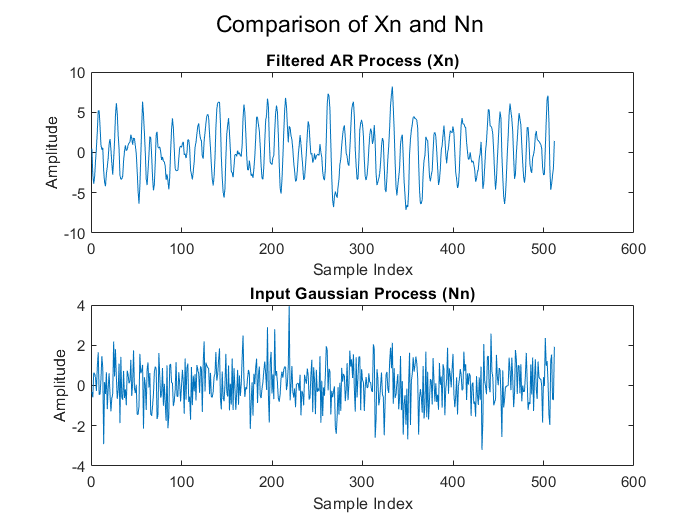

% Number of samples
N = 600; 

% Generate Nn: Zero-mean, unit-variance Gaussian iid random process
Nn = randn(1, N);

% Preallocate Xn with zeros for initial conditions
Xn = zeros(1, N);

% Apply the AR filter: Xn = 1.5*Xn-1 - 0.8*Xn-2 + Nn
for n = 3:N
    Xn(n) = 1.5 * Xn(n-1) - 0.8 * Xn(n-2) + Nn(n);
end

% Discard the first 88 samples and use the last 512 samples
Xn_final = Xn(89:end);
Nn_final = Nn(89:end);

% Plot Xn and Nn using subplot
figure;
subplot(2, 1, 1);
plot(Xn_final);
title('Filtered AR Process (Xn)');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(Nn_final);
title('Input Gaussian Process (Nn)');
xlabel('Sample Index');
ylabel('Amplitude');

% Adjust figure layout
sgtitle('Comparison of Xn and Nn');

The AR filter calculates the present value of a process as a linear combination of its past values. In this case, the AR filter uses the two most recent past values Xn-1 and Xn-2 to calculate Xn. The parameters used as the coefficient are 1.5 for Xn-1 and -0.8 for Xn-2. The Nn gaussian random iid adds randomness to the AR filter. Because the characteristic equation for the parameters z^2 + 1.5z -0.8 lies in the unit circle, the AR filter Xn is stable. In addition, we noticed that the AR filter amplified input as Xn have larger range in comparison to Nn. 

1b) Find autocorrelation function of Nn and Xn for +-50 lags. Plot autocorrelation and power of each signal.

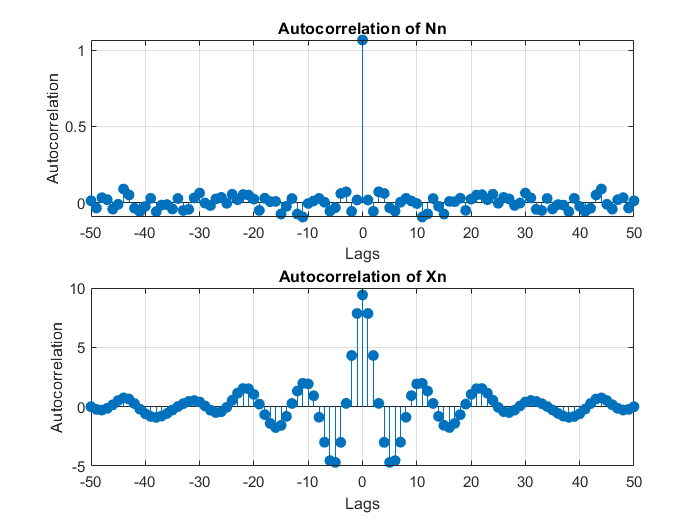

% Autocorrelation for Nn and Xn with +-50 lags
lags = 50;

% Compute autocorrelation
[R_Nn, lags_Nn] = xcorr(Nn_final, lags, 'biased');
[R_Xn, lags_Xn] = xcorr(Xn_final, lags, 'biased');

% Power of each signal
power_Nn = mean(Nn_final.^2); % Mean square value of Nn
power_Xn = mean(Xn_final.^2); % Mean square value of Xn

% Plot the autocorrelation functions
figure;
subplot(2, 1, 1);
stem(lags_Nn, R_Nn, 'filled');
title('Autocorrelation of Nn');
xlabel('Lags');
ylabel('Autocorrelation');
grid on;

subplot(2, 1, 2);
stem(lags_Xn, R_Xn, 'filled');
title('Autocorrelation of Xn');
xlabel('Lags');
ylabel('Autocorrelation');
grid on;


% Display power values
disp(['Power of Nn: ', num2str(power_Nn)]);

Power of Nn: 1.0664


disp(['Power of Xn: ', num2str(power_Xn)]);

Power of Xn: 9.4171


For Nn, a zero-mean, unit-variance white gaussian process, an autocorrelation function with delta function at 0 lag is expected. Indeed, it is trivial that correlation exist when two signal have 0 lag and are the exact the same. 

For Xn, because the characteristic function have complex roots, therefore it will have oscillatory behavior. Thus, the autocorrelation function will display correlation at lag other than 0 lag. 

Moreover, the power of Xn is significantly larger than Nn, which confirms our previous observation that AR filter acts as an amplification for input signals. 

1c) Find PSD of Xn and thereoretical PSD

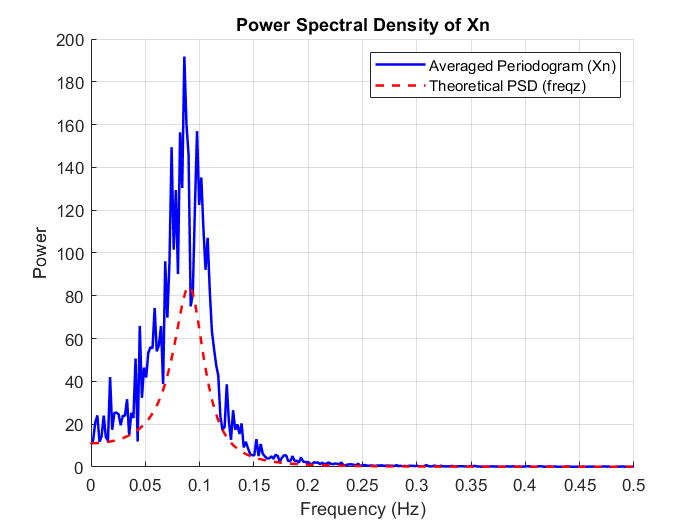

% Parameters
num_samples = 600;   % Total samples per trace
num_traces = 10;     % Number of independent traces
filter_coeffs_a = [1, -1.5, 0.8]; % AR filter coefficients (denominator)
filter_coeffs_b = 1;             % Numerator coefficient

% Preallocation
Nn_traces = randn(num_traces, num_samples);  % 10 traces of Nn
Xn_traces = zeros(size(Nn_traces));

% Generate Xn traces using the AR filter
for i = 1:num_traces
    Xn_traces(i, :) = filter(filter_coeffs_b, filter_coeffs_a, Nn_traces(i, :));
end

% Discard first 88 samples, keep last 512
Nn_traces = Nn_traces(:, 89:end);
Xn_traces = Xn_traces(:, 89:end);

% Periodogram calculation for each trace and averaging
[pxx_Nn, f] = periodogram(Nn_traces(1, :), [], 512, 1); % Example trace for setup
Pxx_Xn = zeros(length(f), num_traces);

for i = 1:num_traces
    [Pxx_Xn(:, i), ~] = periodogram(Xn_traces(i, :), [], 512, 1);
end

Pxx_Xn_avg = mean(Pxx_Xn, 2); % Average periodogram over all traces

% Compute theoretical PSD using freqz
[h, w] = freqz(filter_coeffs_b, filter_coeffs_a, 512, 1); % Frequency response

% Plot results
figure;
hold on;
% plot(f, 10*log10(Pxx_Xn_avg), 'b', 'LineWidth', 1.5); % Averaged periodogram (Xn)
% plot(w, 10*log10(abs(h).^2), 'r--', 'LineWidth', 1.5); % Theoretical PSD (freqz)
plot(f, Pxx_Xn_avg, 'b', 'LineWidth', 1.5); % Averaged periodogram (Xn)
plot(w, abs(h).^2, 'r--', 'LineWidth', 1.5); % Theoretical PSD (freqz)
grid on;
xlabel('Frequency (Hz)');
ylabel('Power');
legend('Averaged Periodogram (Xn)', 'Theoretical PSD (freqz)');
title('Power Spectral Density of Xn');
hold off;

From above plot, we can see that the averaged PSD of Xn follows the general shape of the theoretical PSD. 

1d) Find the power spectral density fo FFT of autocorrelation function

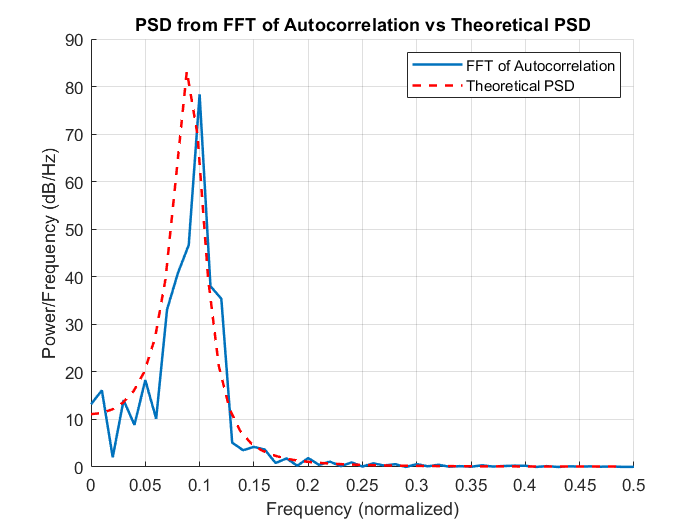

% Parameters
num_samples = 600;   % Total samples
discard_samples = 88; % Initial samples to discard
filter_coeffs_a = [1, -1.5, 0.8]; % AR coefficients
filter_coeffs_b = 1;

% Generate Nn and filter to get Xn
Nn = randn(1, num_samples);  % White noise
Xn = filter(filter_coeffs_b, filter_coeffs_a, Nn);
Xn = Xn(discard_samples+1:end); % Discard first 88 samples

% Compute autocorrelation function
[R_X, lags] = xcorr(Xn, 50, 'unbiased');  % Autocorrelation for ±50 lags

% Compute FFT of autocorrelation function
PSD_fft = abs(fft(R_X));  % Magnitude of FFT
PSD_fft = PSD_fft(1:ceil(end/2));  % Keep only positive frequencies
frequencies = linspace(0, 0.5, length(PSD_fft));  % Normalized frequency axis

% Theoretical PSD using freqz
[theoretical_PSD, theoretical_freq] = freqz(1, filter_coeffs_a, length(PSD_fft), 1);

% Convert PSD to dB/Hz
PSD_fft_db = PSD_fft;
theoretical_PSD_db = abs(theoretical_PSD).^2;

% Plot Results
figure;
hold on;
plot(frequencies, PSD_fft_db, 'LineWidth', 1.5, 'DisplayName', 'FFT of Autocorrelation');
plot(theoretical_freq(1:length(frequencies)), theoretical_PSD_db(1:length(frequencies)), 'r--', ...
    'LineWidth', 1.5, 'DisplayName', 'Theoretical PSD');
grid on;
xlabel('Frequency (normalized)');
ylabel('Power/Frequency (dB/Hz)');
legend;
title('PSD from FFT of Autocorrelation vs Theoretical PSD');
hold off;

The Wiener-Khinchin theorem relates the autocorrelation to the PSD. The FFT of autocorrelation provides the PSD, representing the frequency content of Xn. 

The Periodogram estimates the PSD as the magnitude squared of the DFT signal, which directly calculates the spectral content of the signal. 

Comparing the result from Weiner-Khinichin estimation and Periodogram estimation of PSD, we can tell that the former is a smoother estimation of PSD. Indeed, FFT of autocorrelation exploits the relationship between autocorrelation and the spectrum, often resulting in a less noisy PSD. 

1e) Use the Yule-Walker equations to estimate the best 3-element, 4-element and 5-element of Xn and compare them to the AR filter that generated Xn. 

% Parameters
num_samples = 600;   % Total samples
discard_samples = 88; % Initial samples to discard
filter_coeffs_a = [1, -1.5, 0.8]; % AR(2) coefficients
filter_coeffs_b = 1;

% Generate Nn and filter to get Xn
Nn = randn(1, num_samples);  % White noise
Xn = filter(filter_coeffs_b, filter_coeffs_a, Nn);
Xn = Xn(discard_samples+1:end); % Discard first 88 samples

% Autocorrelation of Xn
[R_X, lags] = xcorr(Xn, 'unbiased');
R_X_pos = R_X(lags >= 0);  % Use only non-negative lags

% AR model orders
orders = [3, 4, 5];
ar_coeffs = cell(length(orders), 1);  % Store coefficients

% Yule-Walker equations
for i = 1:length(orders)
    p = orders(i);
    R = toeplitz(R_X_pos(1:p));        % Toeplitz matrix of autocorrelations
    r = R_X_pos(2:p+1)';              % Autocorrelation vector (lags 1 to p)
    ar_coeffs{i} = R \ r;             % Solve Yule-Walker equations
end

% Compare to true AR(2) coefficients
true_coeffs = [-1.5, 0.8]; % Exclude leading 1 for AR model comparison

% Display results
fprintf('True AR(2) coefficients: %.2f, %.2f\n', true_coeffs);

True AR(2) coefficients: -1.50, 0.80


for i = 1:length(orders)
    fprintf('Estimated AR(%d) coefficients: ', orders(i));
    fprintf('%.2f ', ar_coeffs{i});
    fprintf('\n');
end

Estimated AR(3) coefficients: 

1.46 -0.76 -0.04 

Estimated AR(4) coefficients: 

1.47 -0.75 -0.06 0.01 

Estimated AR(5) coefficients: 

1.47 -0.75 -0.07 0.03 -0.01 

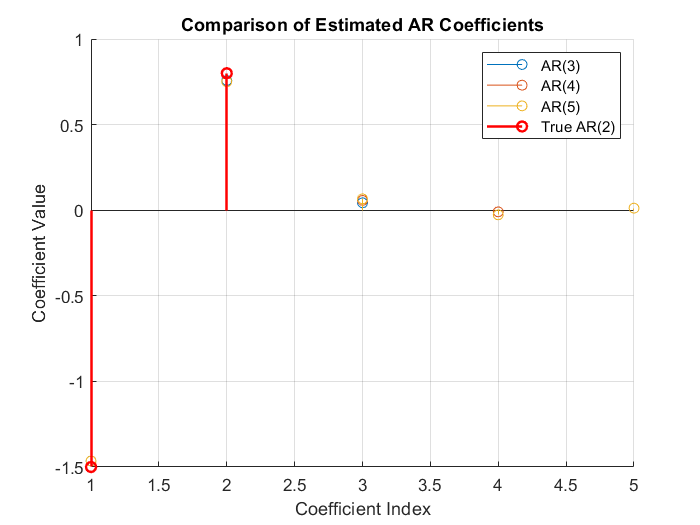


% Plot comparison
figure;
hold on;
for i = 1:length(orders)
    stem(1:orders(i), -ar_coeffs{i}, 'DisplayName', sprintf('AR(%d)', orders(i)));
end
stem(1:length(true_coeffs), true_coeffs, 'r', 'DisplayName', 'True AR(2)', 'LineWidth', 1.5);
grid on;
xlabel('Coefficient Index');
ylabel('Coefficient Value');
title('Comparison of Estimated AR Coefficients');
legend;
hold off;

In comparison to AR(2) which is the true coefficient that generated the Xn process, AR(3), AR(4) and AR(5) may provide a better fit to the Xn process but contain redundant coefficients. 

2a) Generate observation vector Xn = Sn +Wn, where Wn is a zero-mean, unit-variance additive white gaussian noise and Sn = 0.2Sn-1 - 0.8Sn-2 + Nn.

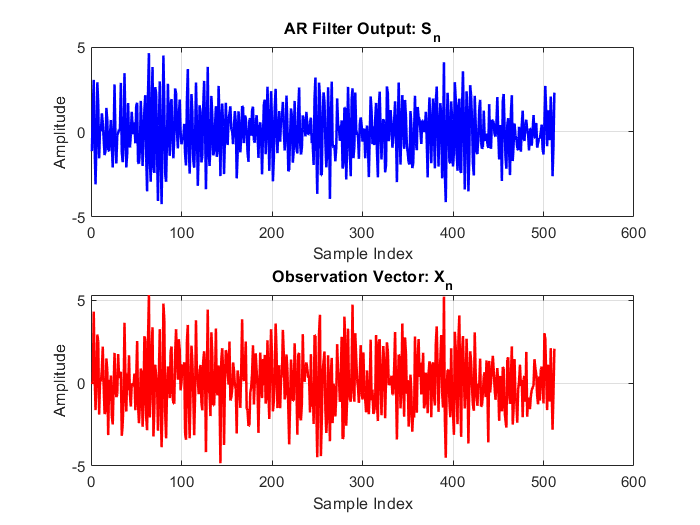

% Parameters
num_samples = 600;          % Total number of samples
discard_samples = 88;       % Number of samples to discard
filter_coeffs_a = [1, -0.2, 0.8]; % AR(2) coefficients for S_n
filter_coeffs_b = 1;

% Generate Nn (white Gaussian noise) and S_n
Nn = randn(1, num_samples);  % Nn: zero-mean, unit-variance
Sn = filter(filter_coeffs_b, filter_coeffs_a, Nn); % Generate S_n
Sn = Sn(discard_samples+1:end); % Discard first 88 samples

% Generate Wn (independent white Gaussian noise)
Wn = randn(1, length(Sn));   % Wn: zero-mean, unit-variance

% Generate Xn = Sn + Wn
Xn = Sn + Wn;

% Plot results
figure;

% Plot S_n
subplot(2, 1, 1);
plot(Sn, 'b', 'LineWidth', 1.5);
title('AR Filter Output: S_n');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Plot X_n
subplot(2, 1, 2);
plot(Xn, 'r', 'LineWidth', 1.5);
title('Observation Vector: X_n');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

2b) Find the sample autocorrelation function Rx(k) for +-256 samples. 

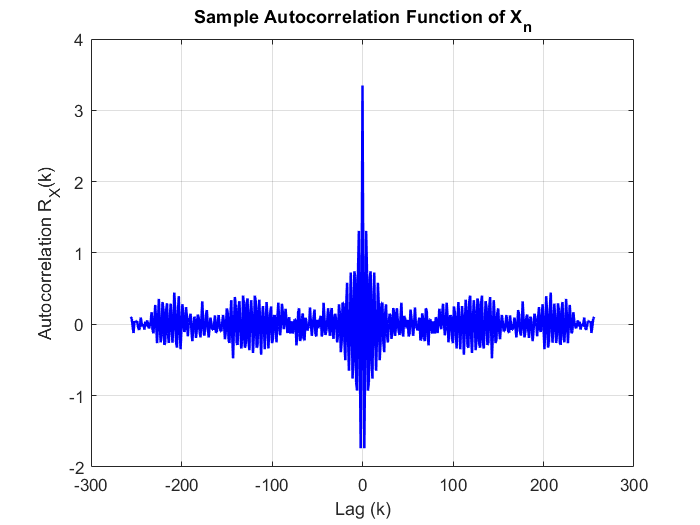

% Compute sample autocorrelation
[R_x, lags] = xcorr(Xn, 256, 'biased'); % Biased autocorrelation for normalization

% Plot the sample autocorrelation function
figure;
plot(lags, R_x, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Lag (k)');
ylabel('Autocorrelation R_X(k)');
title('Sample Autocorrelation Function of X_n');

From the autocorrelation plot above, we can tell that it is an even function.

2c) Find the cross-correlation function Rxs(k).

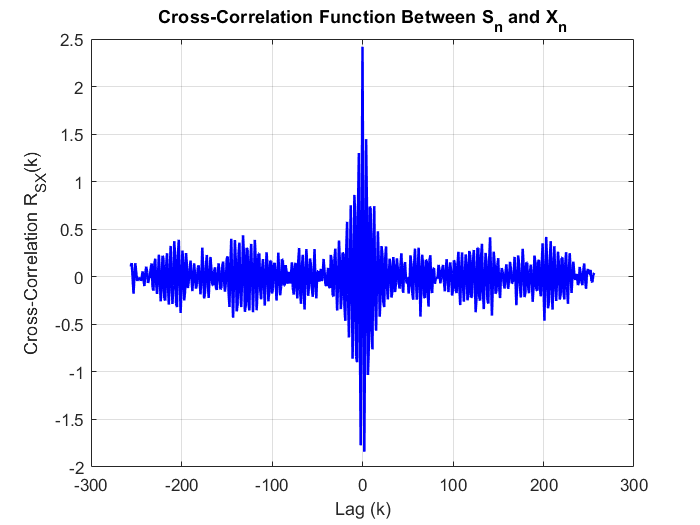

% Compute the cross-correlation between S_n and X_n
[R_sx, lags] = xcorr(Sn, Xn, 256, 'biased'); % Biased normalization

% Plot the cross-correlation function
figure;
plot(lags, R_sx, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Lag (k)');
ylabel('Cross-Correlation R_{SX}(k)');
title('Cross-Correlation Function Between S_n and X_n');

From the crosscorrelation plot above, we can tell that it is an even function

2d) Use the Wiener-Hopf equations to find the 7-element optimal filter as a linear estimator of the desired signal Sn.

% Compute the autocorrelation of X_n up to lag 6 (positive lags only)
R_x = xcorr(Xn, 6, 'biased'); % Biased autocorrelation
R_x = R_x(7:end); % Take positive lags only (lags 0 to 6)
R_x = R_x(:); % Convert R_x to a column vector

% Compute the cross-correlation between S_n and X_n up to lag 6 (positive lags only)
R_sx = xcorr(Sn, Xn, 6, 'biased'); % Biased cross-correlation
R_sx = R_sx(7:end); % Take positive lags only (lags 0 to 6)
R_sx = R_sx(:); % Convert R_sx to a column vector

% Check the dimensions of R_x and R_sx
disp(['Dimensions of R_x: ', num2str(size(R_x))]);

Dimensions of R_x: 7  1


disp(['Dimensions of R_sx: ', num2str(size(R_sx))]);

Dimensions of R_sx: 7  1



% Construct the autocorrelation matrix R_X (size 7x7)
R_X = toeplitz(R_x); % Create a Toeplitz matrix from R_x

% Check the dimension of R_X
disp(['Dimensions of R_X: ', num2str(size(R_X))]);

Dimensions of R_X: 7  7



% Solve the Wiener-Hopf equation R_X * h = R_sx
h = R_X \ R_sx; % Filter coefficients (7-element optimal filter)

% Display the optimal filter coefficients
disp('Optimal filter coefficients h_k:');

Optimal filter coefficients h_k:


disp(h);

   0.568168754736824
   0.013757779291218
  -0.186882669602152
  -0.024618607083455
   0.095782703808712
   0.028856390139138
  -0.035780120543509



2e) Compute the estimation error using the variance of (Sn-Yn) and compare to the value obtained from theoretical error. 

% Calculate the estimation error e_n = S_n - Y_n
Yn = zeros(length(Sn), 1); % Initialize Yn as a column vector of zeros
for n = 7:length(Sn) % Start from n=7 as we're using a 7-element filter
    Yn(n) = sum(h .* Xn(n-6:n)'); % Apply filter (7-element filter)
end

% Compute the estimation error (e_n = S_n - Y_n)
e_n = Sn - Yn; % Estimation error

% Compute the variance of the estimation error (sample variance)
error_variance = var(e_n); % Variance of estimation error

% Compute thXn_finale theoretical estimation error variance
R_s0 = 1; % R_s(0) = var(Sn) = 1 (since S_n is unit-variance)
theoretical_error_variance = R_s0 - sum(h .* R_sx); % Using the formula

% Display the results
disp(['Variance of the estimation error (computed): ', num2str(error_variance)]);

Variance of the estimation error (computed): 1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081      1.9081 

disp(['Theoretical variance of the estimation error: ', num2str(theoretical_error_variance)]);

Theoretical variance of the estimation error: -0.92406


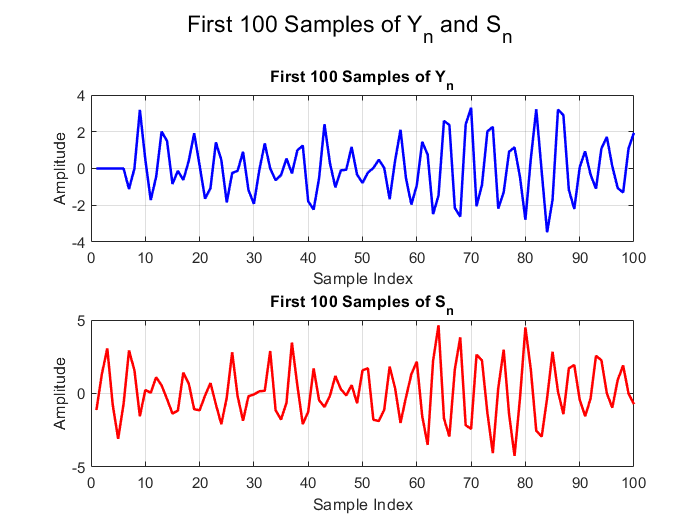

% Plot the first 100 samples
figure;

% Plot Zn
subplot(2, 1, 1);
plot(Yn(1:100), 'b', 'LineWidth', 1.5);
title('First 100 Samples of Y_n');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Plot Sn
subplot(2, 1, 2);
plot(Sn(1:100), 'r', 'LineWidth', 1.5);
title('First 100 Samples of S_n');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Display the figure
sgtitle('First 100 Samples of Y_n and S_n');